# 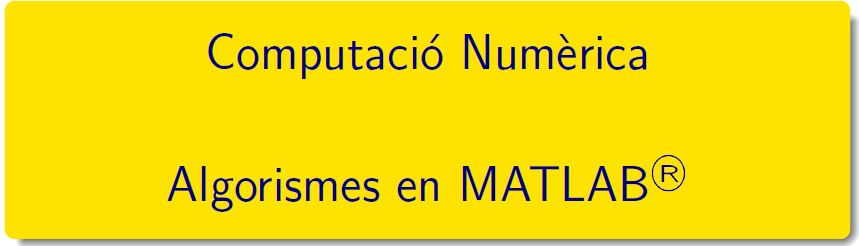

# Pràctica 2 - Activitat 1: Conceptes Bàsics (revisió pràctica 1)

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

### Practiquem les funcions

#### Exercici 6, pàgina 23. [Funcions anònimes](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

`h = @(``arglist``)``anonymous_function`

**6**  Avalueu les funcions  $\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$ per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$ 

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. Feu un joc de proves prenent $2^{-n},5^{-n},7^{-n},10^{-n}, \dots$

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

clearvars
format long
f = @(x) sqrt(x.^2+1)-1 

f = function_handle with value:
    @(x)sqrt(x.^2+1)-1


g = @(x) x.^2./(sqrt(x.^2+1)+1)

g = function_handle with value:
    @(x)x.^2./(sqrt(x.^2+1)+1)


y = [1:25]

y =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


y = 8.^(-y)

y =    0.125000000000000   0.015625000000000   0.001953125000000   0.000244140625000   0.000030517578125   0.000003814697266   0.000000476837158   0.000000059604645   0.000000007450581   0.000000000931323   0.000000000116415   0.000000000014552   0.000000000001819   0.000000000000227   0.000000000000028   0.000000000000004   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000


f(y)==g(y)

ans = 1×25 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


#### Exercici 8, pàgina 23. [Funcions en Live script](https://es.mathworks.com/help/matlab/ref/function.html)

`function f = nom_fun(``arglist``)`

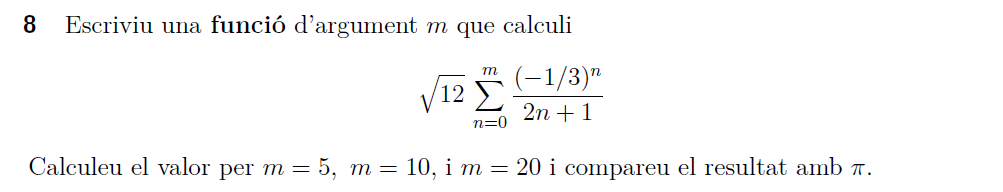

f(m) = sqrt(12)*sum(@(i) (-1/3)^i/(2i+1) ([1:m]),'all')


Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

## 2. Algorismes: Estabilitat numèrica i problemes ben condicionats

**(ja eren al document prac01)**

#### Exercici 11, pàgina 23. **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos mètodes iteratius diferents:

	            
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

- apartat a)

- apartat b)

- valor aproximat per integració numèrica


integral(@(x)x.^2.*exp(x-1),0,1);


- Taula comparativa de resultats

- Taula comparativa d'errors

## 3. Pràctica

#### Exercici 10, pàgina 23.  Sumar sèrie $e^x$

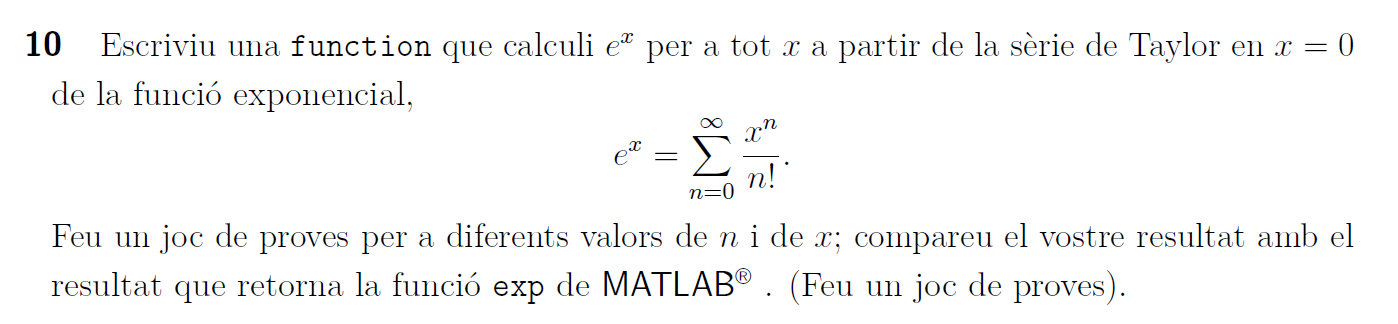     

#### Exercici 12, pàgina 23.  Sumar sèrie $\sin(x)$

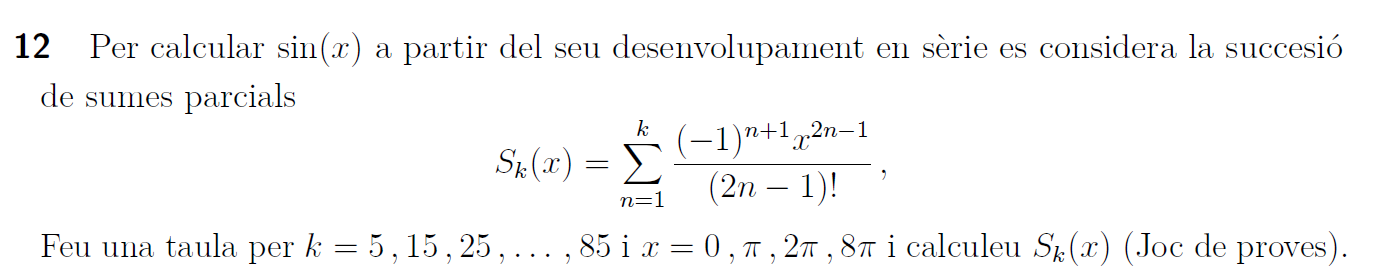

`Document preparat per M. Àngela Grau Gotés, 22 de febrer de 2023`